%%%%%%%%%%    Hw2 - point b  %%%%%%%%
%% %% GoooooD copy from point a %%%%%
%% Full Signal Processing and Analysis System
clear; clc; close all;

% Load data
load('Hw2b.mat');
s_in  = Sin_b(:, [2, 1]);   % 交换通道：恢复 左 ←→ 右  % Noisy signal [N x 2]
s_ref = Sn_ref_b;   % Reference noise [N x 2]

lag_correction = 3;
s_ref = [s_ref(lag_correction+1:end, :); zeros(lag_correction, size(s_ref,2))];

% Normalize
s_in = s_in / max(abs(s_in(:)));
s_ref = s_ref / max(abs(s_ref(:)));
[N, num_ch] = size(s_in);
fprintf('Total Duration: %.2f seconds\n', N/fs);

Total Duration: 74.01 seconds



%% Pre-filtering (Bandpass before processing)
f_low = 100;    
f_high = 5000;  
order = 6;      
[b_bp, a_bp] = butter(order, [f_low, f_high]/(fs/2), 'bandpass');

for ch = 1:num_ch
    s_in(:, ch) = filtfilt(b_bp, a_bp, s_in(:, ch));
    s_ref(:, ch) = filtfilt(b_bp, a_bp, s_ref(:, ch));
end

%% NLMS Denoising
L_nlms = 64;       
mu = 0.02;         
delta = 1e-6;      
s_nlms = zeros(N, num_ch);
fprintf('\nStarting NLMS denoising...\n');


Starting NLMS denoising...


tic;

for ch = 1:num_ch
    w = zeros(L_nlms, 1);  
    for n = L_nlms:N
        x = s_ref(n:-1:n-L_nlms+1, ch);
        d = s_in(n, ch);
        y = w' * x;
        e = d - y;
        s_nlms(n, ch) = e;
        w = w + (mu * e * x) / (x' * x + delta);
    end
end

fprintf('NLMS completed in %.2f seconds.\n', toc);

NLMS completed in 0.95 seconds.



%% Kalman Post-Processing
Q = 10e-6;    
R = 0.01;    
s_kalman = zeros(N, num_ch);
fprintf('Starting Kalman post-processing...\n');

Starting Kalman post-processing...


tic;

for ch = 1:num_ch
    x_hat = 0;
    P = 1;
    for n = 1:N
        x_hat_minus = x_hat;
        P_minus = P + Q;
        K = P_minus / (P_minus + R);
        x_hat = x_hat_minus + K * (s_nlms(n, ch) - x_hat_minus);
        P = (1 - K) * P_minus;
        s_kalman(n, ch) = x_hat;
    end
end

fprintf('Kalman completed in %.2f seconds.\n', toc);

Kalman completed in 0.02 seconds.



%% Normalize Final Outputs
s_nlms = s_nlms / max(abs(s_nlms(:)));
s_kalman = s_kalman / max(abs(s_kalman(:)));

%% Noise/SNR Analysis
noise_nlms = s_in - s_nlms;
noise_kalman = s_in - s_kalman;
noise_energy_orig = mean(s_ref.^2);
noise_energy_nlms = mean(noise_nlms.^2);
noise_energy_kalman = mean(noise_kalman.^2);
signal_energy = mean(s_in.^2);
snr_orig = 10*log10(signal_energy ./ noise_energy_orig);
snr_nlms = 10*log10(signal_energy ./ noise_energy_nlms);
snr_kalman = 10*log10(signal_energy ./ noise_energy_kalman);

fprintf('\nNoise Energy (L/R):  Orig: %.4f / %.4f | NLMS: %.4f / %.4f | Kalman: %.4f / %.4f\n', ...
    noise_energy_orig(1), noise_energy_orig(2), noise_energy_nlms(1), noise_energy_nlms(2), noise_energy_kalman(1), noise_energy_kalman(2));


Noise Energy (L/R):  Orig: 0.0136 / 0.0142 | NLMS: 0.0138 / 0.0124 | Kalman: 0.0301 / 0.0195


fprintf('SNR (dB):            Orig: %.2f / %.2f | NLMS: %.2f / %.2f | Kalman: %.2f / %.2f\n', ...
    snr_orig(1), snr_orig(2), snr_nlms(1), snr_nlms(2), snr_kalman(1), snr_kalman(2));

SNR (dB):            Orig: 0.69 / -0.13 | NLMS: 0.61 / 0.48 | Kalman: -2.76 / -1.49


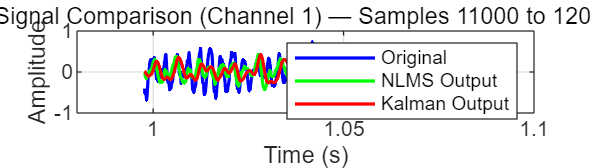


% %% Visualization
% t = (0:N-1)/fs;
% figure('Name', 'Time-Domain Comparison', 'Position', [100, 100, 1400, 800]);
% subplot(3,1,1); plot(t, s_in(:,1)); title('Original Noisy Signal'); xlabel('Time (s)'); ylabel('Amplitude');
% subplot(3,1,2); plot(t, s_nlms(:,1)); title('NLMS Output'); xlabel('Time (s)'); ylabel('Amplitude');
% subplot(3,1,3); plot(t, s_kalman(:,1)); title('Kalman Output'); xlabel('Time (s)'); ylabel('Amplitude');
% 

%% Visualization (Zoomed Signal Comparison: Samples 11000–12000)
start_idx = 11000;
end_idx = 12000;
t_zoom = (start_idx:end_idx) / fs;

figure('Name', 'Zoomed Time-Domain Comparison (11000–12000)', 'Position', [100, 100, 1400, 400]);
plot(t_zoom, Sin_b(start_idx:end_idx,1), 'b', 'LineWidth', 1.2); hold on;
plot(t_zoom, s_nlms(start_idx:end_idx,1), 'g', 'LineWidth', 1.2);
plot(t_zoom, s_kalman(start_idx:end_idx,1), 'r', 'LineWidth', 1.2); hold off;
xlabel('Time (s)');
ylabel('Amplitude');
title('Signal Comparison (Channel 1) — Samples 11000 to 12000');
legend('Original', 'NLMS Output', 'Kalman Output');
grid on;

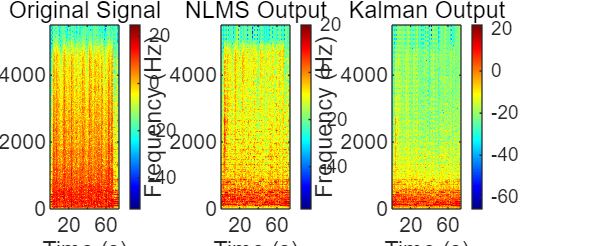





% %% Spectrum Plot
% figure('Name', 'Spectral Analysis', 'Position', [100, 100, 1200, 500]);
% [P_in, f] = pwelch(s_in(:,1), 2048, 1024, 2048, fs);
% [P_nlms, ~] = pwelch(s_nlms(:,1), 2048, 1024, 2048, fs);
% [P_kalman, ~] = pwelch(s_kalman(:,1), 2048, 1024, 2048, fs);
% 
% subplot(1,2,1);
% semilogx(f, 10*log10(P_in), 'b', f, 10*log10(P_nlms), 'g', f, 10*log10(P_kalman), 'r');
% legend('Original', 'NLMS', 'Kalman'); grid on;
% title('Full Spectrum'); xlabel('Hz'); ylabel('dB'); xlim([20 20000]);
% 
% subplot(1,2,2);
% plot(f, 10*log10(P_in), 'b', f, 10*log10(P_nlms), 'g', f, 10*log10(P_kalman), 'r');
% xlim([f_low, f_high]); title('Guitar Frequency Focus');
% legend('Original', 'NLMS', 'Kalman'); grid on;
% xlabel('Hz'); ylabel('dB');

%% Time-Frequency Spectrograms (Centered, Clean Layout)
window_length = 1024;
overlap = round(0.75 * window_length);
nfft = 2048;

% Compute Spectrograms
[S1,F1,T1] = spectrogram(Sin_b(:,1), window_length, overlap, nfft, fs);
[S2,F2,T2] = spectrogram(s_nlms(:,1), window_length, overlap, nfft, fs);
[S3,F3,T3] = spectrogram(s_kalman(:,1), window_length, overlap, nfft, fs);

% Create a blank figure
figure('Name', 'Time-Frequency Spectrograms (Channel 1)', 'Position', [100, 100, 1600, 600], 'Color', 'w');

% Axes dimensions (manually controlled for centered layout)
w = 0.25;         % width of each axes
h = 0.75;         % height of each axes
y = 0.15;         % bottom margin
gap = 0.04;       % gap between axes
start_x = (1 - (3*w + 2*gap)) / 2;  % center all three axes

% ---- Plot 1: Original ----
ax1 = axes('Position', [start_x, y, w, h]);
imagesc(T1, F1, 10*log10(abs(S1) + 1e-12)); axis xy;
colormap jet; colorbar;
title('Original Signal');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

% ---- Plot 2: NLMS ----
ax2 = axes('Position', [start_x + w + gap, y, w, h]);
imagesc(T2, F2, 10*log10(abs(S2) + 1e-12)); axis xy;
colormap jet; colorbar;
title('NLMS Output');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

% ---- Plot 3: Kalman ----
ax3 = axes('Position', [start_x + 2*(w + gap), y, w, h]);
imagesc(T3, F3, 10*log10(abs(S3) + 1e-12)); axis xy;
colormap jet; colorbar;
title('Kalman Output');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

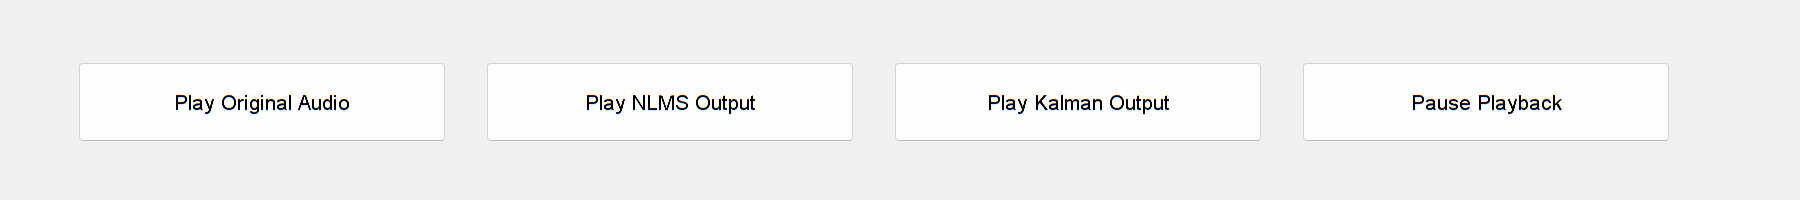






%% Playback UI
f_ui = figure('Name', 'Audio Playback Control', 'Position', [200, 200, 900, 100]);
bw = 184; bh = 40; bs = 20; sx = 40;

uicontrol('Style', 'pushbutton', 'String', 'Play Original Audio', ...
    'Position', [sx, 30, bw, bh], 'Callback', @(src,evt) sound(s_in, fs));
uicontrol('Style', 'pushbutton', 'String', 'Play NLMS Output', ...
    'Position', [sx + (bw+bs), 30, bw, bh], 'Callback', @(src,evt) sound(s_nlms, fs));
uicontrol('Style', 'pushbutton', 'String', 'Play Kalman Output', ...
    'Position', [sx + 2*(bw+bs), 30, bw, bh], 'Callback', @(src,evt) sound(s_kalman, fs));
uicontrol('Style', 'pushbutton', 'String', 'Pause Playback', ...
    'Position', [sx + 3*(bw+bs), 30, bw, bh], 'Callback', 'clear sound');


%% Save Audio
audiowrite('original.wav', s_in, fs);
audiowrite('nlms_output.wav', s_nlms, fs);
audiowrite('kalman_output.wav', s_kalman, fs);
save('denoising_results_final.mat', 's_in', 's_ref', 's_nlms', 's_kalman', 'fs');
fprintf('\nAll audio and data saved.\n');


All audio and data saved.
